# Unsaturated flow

clear, clc, close all

Properties of three common soil types: sand, loam and clay

% 1) Sand
sand.Ks = 505.8; % [cm/d]
sand.theta_r = 0.058; %
sand.theta_s = 0.37; %
sand.alpha = 0.035; % [1/cm]
sand.n = 3.19;
% 2) Loam
loam.Ks = 38.3; % [cm/d]
loam.theta_r = 0.083; %
loam.theta_s = 0.46; 
loam.alpha = 0.025; % [1/cm]
loam.n = 1.31;
% 3) Clay
clay.Ks = 26.0; % [cm/d]
clay.theta_r = 0.102;
clay.theta_s = 0.51;
clay.alpha = 0.021; % [1/cm]
clay.n = 1.2;

% 4) Silt loam

silt_loam.VG.Ks = 30.5; % [cm/d]
silt_loam.VG.theta_s = 0.513;
silt_loam.VG.theta_r = 0.05;
silt_loam.VG.alpha = 0.417/100; % [1/cm]
silt_loam.VG.n = 1.75; %

silt_loam.BC.Ks = 30.5; % [cm/d]
silt_loam.BC.theta_s = 0.513;
silt_loam.BC.lambda = 0.54;
silt_loam.BC.theta_r = 0.03;
silt_loam.BC.hb = 1.48*100; % [cm]

% Experimental data (Or et al. 1991)
theta_data = [0.0437    0.0994    0.1206    0.1464    0.1903    0.2291    0.2890    0.3736    0.4295    0.4496];
h_data = [615.7201   86.1818   30.0603   19.9140    9.9190    7.0111    4.9791    2.9845    1.9950    0.9044]*100; %[cm]

## Soil Water Content

The **van Genuchten model** for soil water content is

thetaVG = @(h,rock) rock.theta_r + (rock.theta_s-rock.theta_r)./(1+(rock.alpha*abs(h)).^rock.n).^(1-1/rock.n);
thetaBC = @(h,rock) rock.theta_r + (rock.theta_s-rock.theta_r).*(rock.hb./abs(h)).^rock.lambda.*(h>rock.hb)+(rock.theta_s-rock.theta_r)*(h<=rock.hb);

Plot SWC curves for different rocks

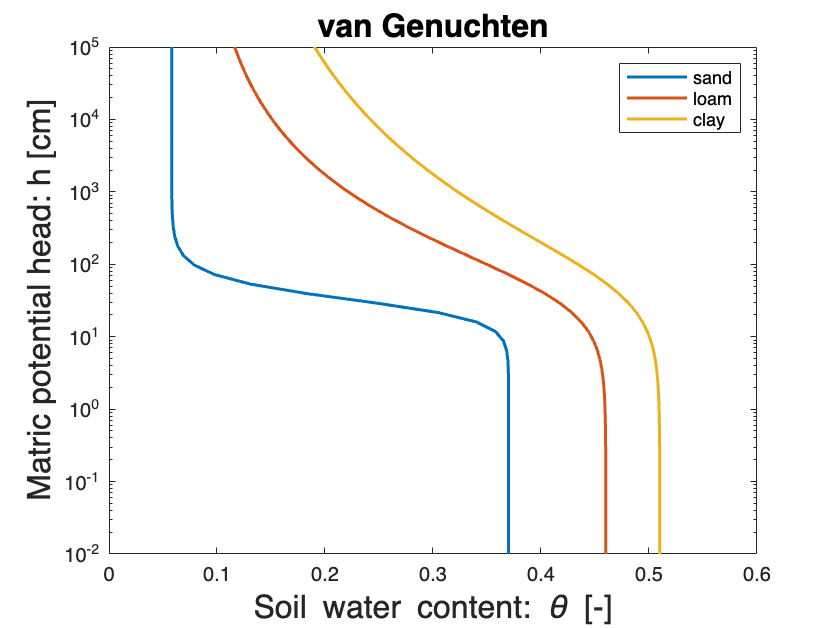

% 1) Sand
h = logspace(-3,10,1e2);
theta_sand = thetaVG(h,sand);
theta_loam = thetaVG(h,loam);
theta_clay = thetaVG(h,clay);
clf
semilogy(theta_sand,h,'LineWidth',1.5), hold on
semilogy(theta_loam,h,'LineWidth',1.5)
semilogy(theta_clay,h,'LineWidth',1.5)
ylim([1e-2 1e5])
legend('sand','loam','clay')
ylabel('Matric potential head: h [cm]','fontsize',16)
xlabel('Soil water content: \theta [-]','fontsize',16)
title('van Genuchten','fontsize',16)

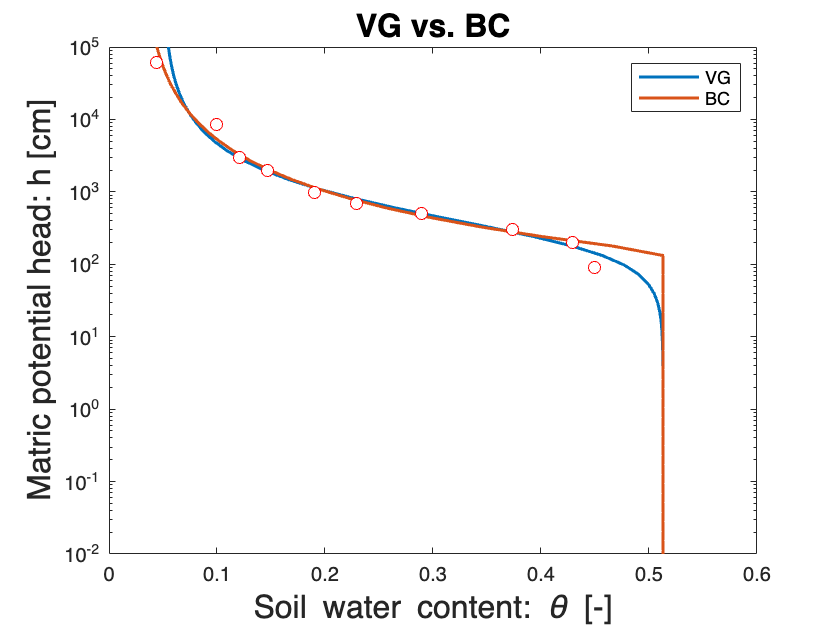


figure
theta_vg = thetaVG(h,silt_loam.VG);
theta_bc = thetaBC(h,silt_loam.BC);
semilogy(theta_vg,h,'LineWidth',1.5), hold on
semilogy(theta_bc,h,'LineWidth',1.5)
semilogy(theta_data,h_data,'ro','markerfacecolor','w')
legend('VG','BC')
ylim([1e-2 1e5])
ylabel('Matric potential head: h [cm]','fontsize',16)
xlabel('Soil water content: \theta [-]','fontsize',16)
title('VG vs. BC','fontsize',16)

## Unsaturated Hydraulic Conductivity

The unsaturted hydraulic diffusivity in the van Genuchten model is given by

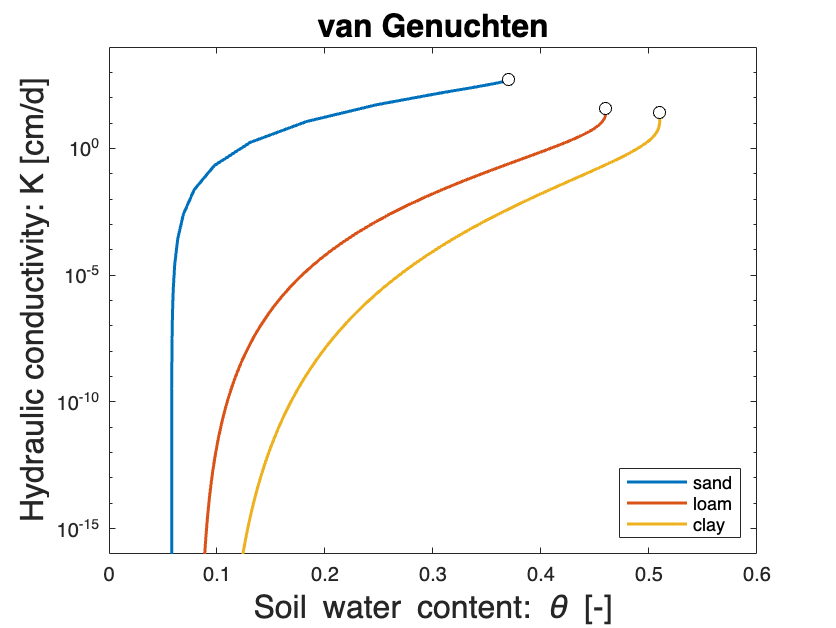

% theta_sand = 
sat = @(theta,rock) (theta-rock.theta_r)/(rock.theta_s-rock.theta_r);

KVGs = @(theta,rock) rock.Ks*sqrt(sat(theta,rock)).*(1-(1-sat(theta,rock).^(rock.n/(rock.n-1))).^(1-1/rock.n)).^2;
KBCs = @(theta,rock) rock.Ks*sat(theta,rock).^(3+2/rock.lambda);

figure
semilogy(theta_sand,KVGs(theta_sand,sand),'LineWidth',1.5), hold on
semilogy(theta_loam,KVGs(theta_loam,loam),'LineWidth',1.5)
semilogy(theta_clay,KVGs(theta_clay,clay),'LineWidth',1.5)
semilogy(sand.theta_s,sand.Ks,'ko','MarkerFaceColor','w')
semilogy(loam.theta_s,loam.Ks,'ko','MarkerFaceColor','w')
semilogy(clay.theta_s,clay.Ks,'ko','MarkerFaceColor','w')
xlim([0 0.6])
ylim([1e-16 1e4])
legend('sand','loam','clay','Location','southeast')
ylabel('Hydraulic conductivity: K [cm/d]','fontsize',16)
xlabel('Soil water content: \theta [-]','fontsize',16)
title('van Genuchten','fontsize',16)

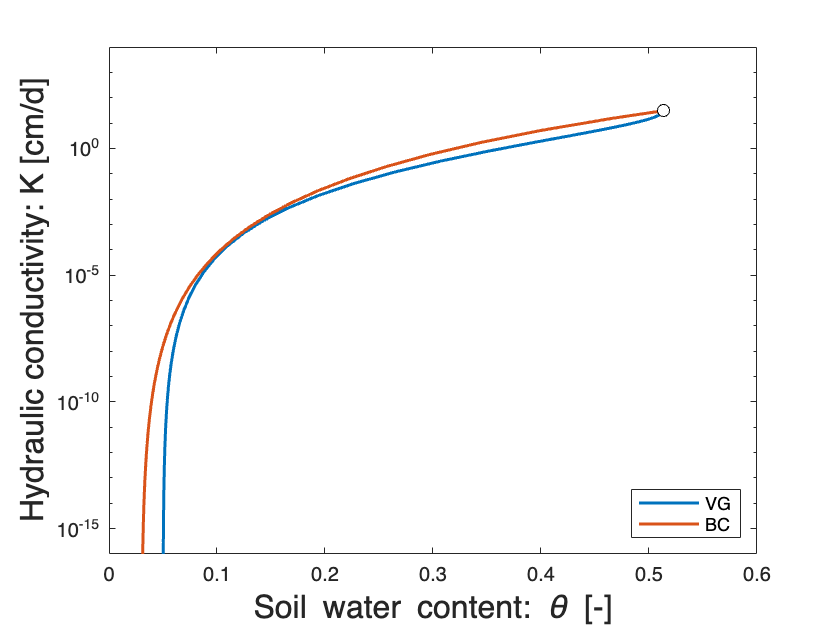


figure
semilogy(theta_vg,KVGs(theta_vg,silt_loam.VG),'LineWidth',1.5), hold on
semilogy(theta_bc,KBCs(theta_bc,silt_loam.BC),'LineWidth',1.5), hold on
semilogy(silt_loam.VG.theta_s,silt_loam.VG.Ks,'ko','MarkerFaceColor','w')
semilogy(silt_loam.BC.theta_s,silt_loam.BC.Ks,'ko','MarkerFaceColor','w')
xlim([0 0.6])
ylim([1e-16 1e4])
legend('VG','BC','Location','southeast')
ylabel('Hydraulic conductivity: K [cm/d]','fontsize',16)
xlabel('Soil water content: \theta [-]','fontsize',16)

## Hydraulic Diffusivity

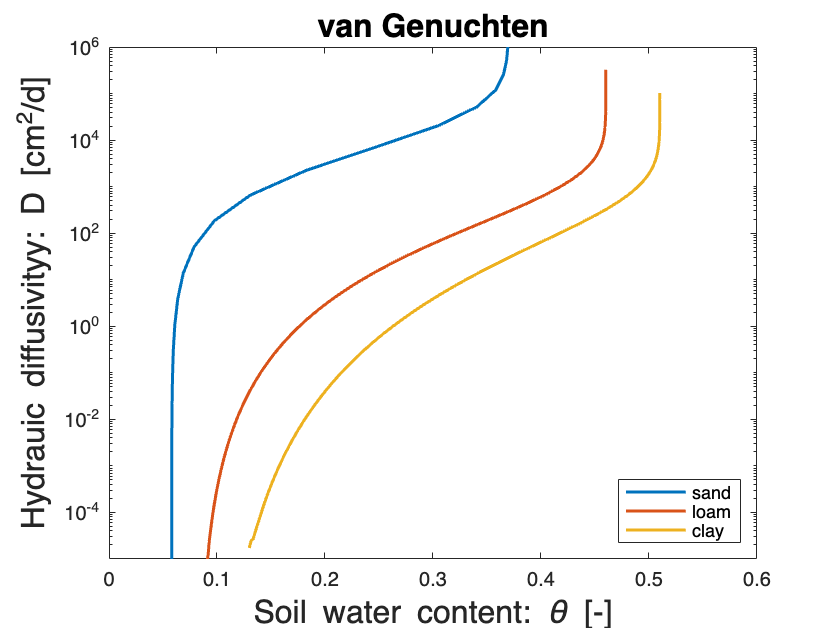

DVG = @(theta,rock) rock.Ks/(rock.alpha*(rock.n-1)*(rock.theta_s-rock.theta_r))*sat(theta,rock).^(.5-rock.n/(rock.n-1)).*((1-sat(theta,rock).^(rock.n/(rock.n-1))).^((1-rock.n)/rock.n)+ ...
    (1-sat(theta,rock).^(rock.n/(rock.n-1))).^((rock.n-1)/rock.n)-2);
DBC = @(theta,rock) rock.Ks*rock.hb/(rock.lambda*(rock.theta_s-rock.theta_r))*sat(theta,rock).^(2+1/rock.lambda);

figure
semilogy(theta_sand,DVG(theta_sand,sand),'LineWidth',1.5), hold on
semilogy(theta_loam,DVG(theta_loam,loam),'LineWidth',1.5)
semilogy(theta_clay,DVG(theta_clay,clay),'LineWidth',1.5)
legend('sand','loam','clay','Location','southeast')
xlim([0 0.6])
ylim([1e-5 1e6])
xlabel('Soil water content: \theta [-]','fontsize',16)
ylabel('Hydrauic diffusivityy: D [cm^2/d]','fontsize',16)
title('van Genuchten','fontsize',16)

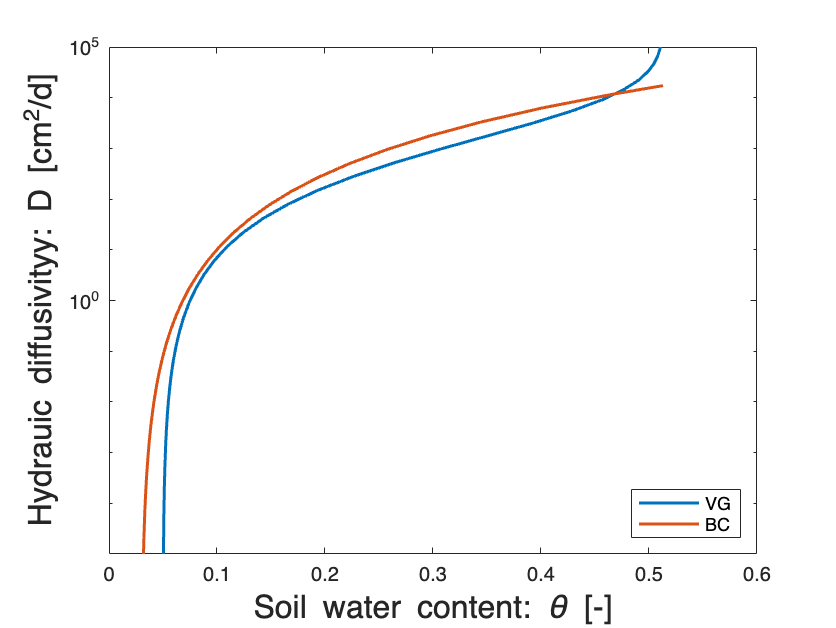


figure
semilogy(theta_vg,DVG(theta_vg,silt_loam.VG),'LineWidth',1.5), hold on
semilogy(theta_bc,DBC(theta_bc,silt_loam.BC),'LineWidth',1.5), hold on
xlim([0 0.6])
ylim([1e-5 1e5])
legend('VG','BC','Location','southeast')
ylabel('Hydrauic diffusivityy: D [cm^2/d]','fontsize',16)
xlabel('Soil water content: \theta [-]','fontsize',16)

## Solving capillary diffusion

Consider a horizontal column filled with soil so that infiltration is driven only by capillary diffusion

PDE: $\frac{\partial \theta}{\partial t} 
+ \nabla\cdot\left[D(\theta) \nabla\theta\right] = 0$

IC: $\theta(x,t=0) = \theta_0$

BC: $\theta(x=0,t) = \theta_b$

For simplicity we will consider the Brooks-Corey (BC) hydraulic diffusivity


$$K(\theta) = K_s\left(\frac{\theta-\theta_r}{\theta_s-\theta_r}\right)^{3+\frac{2}{\lambda}}$$


with the values for silty loam used above. Due to the dependence of the hydraulic diffusivity on the water content this problem is non-linear. The large variation of $D(\theta)$ (10 orders of magnitude!) makes this problem highly non-linear!

### Explicit solution

The simplest approach is to solve the non-linear problem is to solve it explicitly so that the hydraulic conductivity can be evaluated at the last time step.

theta_0 = silt_loam.BC.theta_r+0.001;
theta_b = silt_loam.BC.theta_s-0.001;
tmax = 1;
alpha = 1; % Explicit
alpha = 0; % Implicit
% alpha = 0.5: % CN
Nt = 1e4;
Grid.xmin = 0; Grid.xmax = 100; Grid.Nx = 200;
Grid = build_grid(Grid);

% Build operatror
[D,G,~,I,M] = build_ops(Grid);
Kd = @(theta) comp_mean(DBC(theta,silt_loam.BC),M,1,Grid,1);
L = @(theta) -D*Kd(theta)*G;
IM = @(theta,alpha,dt) I + dt*(1-alpha)*L(theta);
EX = @(theta,alpha,dt) I - dt*alpha*L(theta);
fs = spalloc(Grid.N,1,0);

% Build BC's
BC.dof_dir   = Grid.dof_xmin;
BC.dof_f_dir = Grid.dof_f_xmin;
BC.g = theta_b;
BC.dof_neu   = [];
BC.dof_f_neu = [];
BC.qb        = [];
[B,N,fn] = build_bnd(BC,Grid,I);

% IC
theta = theta_0*ones(Grid.N,1);

% Time step restrition
D0 = DBC(theta_0,silt_loam.BC)

D0 = 7.9443e-07

Db = DBC(theta_b,silt_loam.BC)

Db = 1.7169e+04

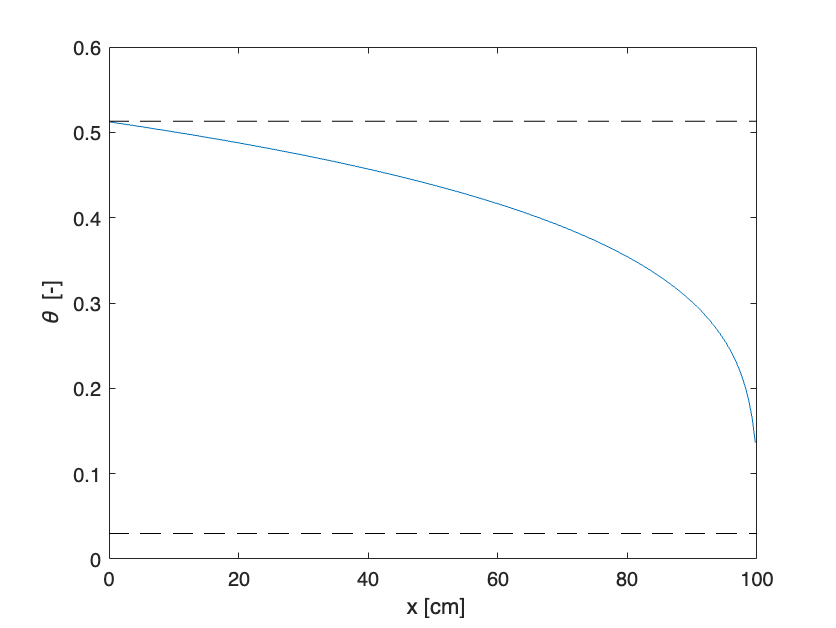

Dmax = max(D0,Db);

% time stepping loop
if alpha ==1
    dtmax = Grid.dx^2/2/Dmax;
    Nt = ceil(tmax/dtmax)+10
end

dt = tmax/Nt;

for n = 1:Nt
    
    if alpha == 0.5
        theta_p = solve_lbvp(IM(theta,alpha,dt),dt*fs+EX(theta,alpha,dt)*theta,B,BC.g,N);
        theta_guess = (theta+theta_p)/2;
        theta = solve_lbvp(IM(theta_guess,alpha,dt),dt*fs+EX(theta_guess,alpha,dt)*theta,B,BC.g,N);
    else
        theta = solve_lbvp(IM(theta,alpha,dt),dt*fs+EX(theta,alpha,dt)*theta,B,BC.g,N);
    end
end

figure
plot(Grid.xc,theta), hold on
plot([0 100],silt_loam.BC.theta_r*[1 1],'k--')
plot([0 100],silt_loam.BC.theta_s*[1 1],'k--')
xlabel ' x [cm]'
ylabel '\theta [-]'